# 'Continuum mechanics for tectonics' 

# Assignment (Week 6)

## Anti-plane strain problems

For a vertical fault of length $w$, the top edge of this fault is located at $y_2 ,y_3$, the displacement Green's functions (unit slip) are


$$u_1 \left(x_2 ,x_3 ;y_2 ,y_3 \right)=\frac{1}{2\pi \;}\left({\mathrm{tan}}^{-1} \frac{x_3 -y_3 }{x_2 -y_2 }-{\mathrm{tan}}^{-1} \frac{x_3 +y_3 }{x_2 -y_2 }+{\mathrm{tan}}^{-1} \frac{x_3 -y_3 -w}{x_2 -y_2 }-{\mathrm{tan}}^{-1} \frac{x_3 +y_3 +w}{x_2 -y_2 }\right)$$


The corresponding stresses $\sigma_{12}$ and $\sigma_{13}$ can be calculated as $\sigma_{\mathrm{ij}} =G\frac{\;\partial u_i }{\partial x_j }$

- Using the same principles we used to derive the above expressions, derive the displacement and stress Green's functions for slip on a fault of length $w$ and dipping at an angle $\delta$ to the horizontal.

- Compute an analytical expression for shear traction $\sigma_s$ on this fault.

- To simulate interseismic loading of the system, we generally set $w\to\infty$. This is identical to the dislocation description of faults you have encountered in Paul Segall's textbook. Assuming this process is time-invariant i.e. $\frac{\partial \;}{\partial t\;}=0$, the corresponding velocity and stress-rate fields are called the interseismic velocity field and stressing-rates. Show that the interseismic velocity field for a strike-slip fault as seen on the free surface does not depend on the dip angle of the fault, but only depends on the location of the top edge of the fault.

- Another way to compute the interseismic component of stress and displacement is to use the 'back-slip model'. Based on the suggested readings and Paul Segall's textbook, first describe what you understand of the back-slip model, and then explain why the back-slip model is mathematically identical to the deep semi-infinite dislocation model.

## Stress changes due to fault slip

You have been recruited to study a recent earthquake that occurred on an unmapped fault. The results of a recent geodetic transect across this fault is shown below. The displacement observations are provided to you in the file '*eq1_obs.dat*'.

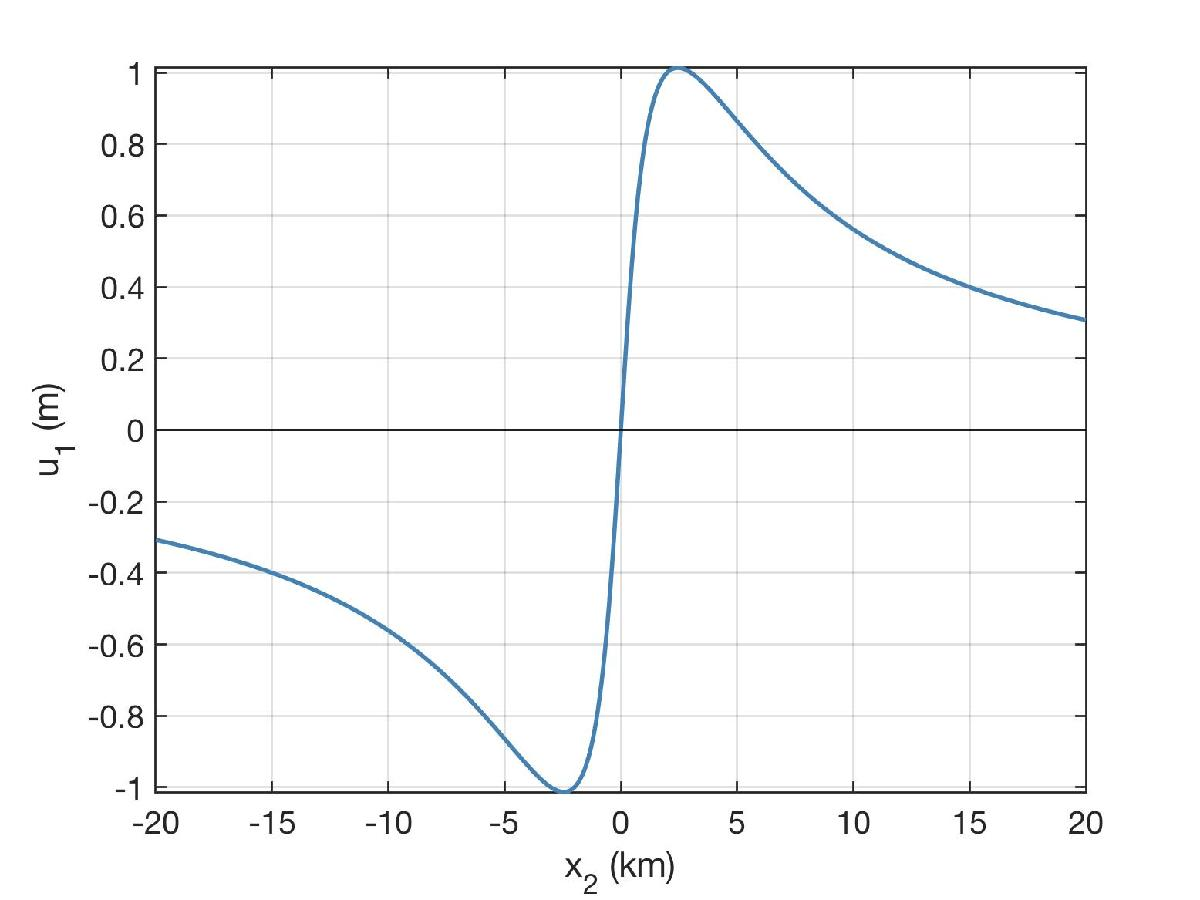

- For a vertical fault of down-dip length $w$ = 20 km, mesh this fault using line elements of width $\Delta w$ = 0.5 km. Construct a matrix of displacement Greens functions, $G_{ij}$, relating slip on each fault patch $s_j$ to displacement at each observation location $u_i$.

- Use the matrix $G_{ij}$ and observations $u_i$ to infer slip on each fault patch. The inverse problem appears to be well-posed in terms of number of observations, model parameters and observation equations, but is it actually over-determined?

- To assist you with this problem, a seismologist steps in and provides you with a catalogue of microseismicity/aftershocks following this event. You now have the locations and dips of a number of micro-faults that were triggered by the mainshock. Additionally the seismologist also computed the stress drop for each event. Provided in '*aftershock_catalogue.dat*'.

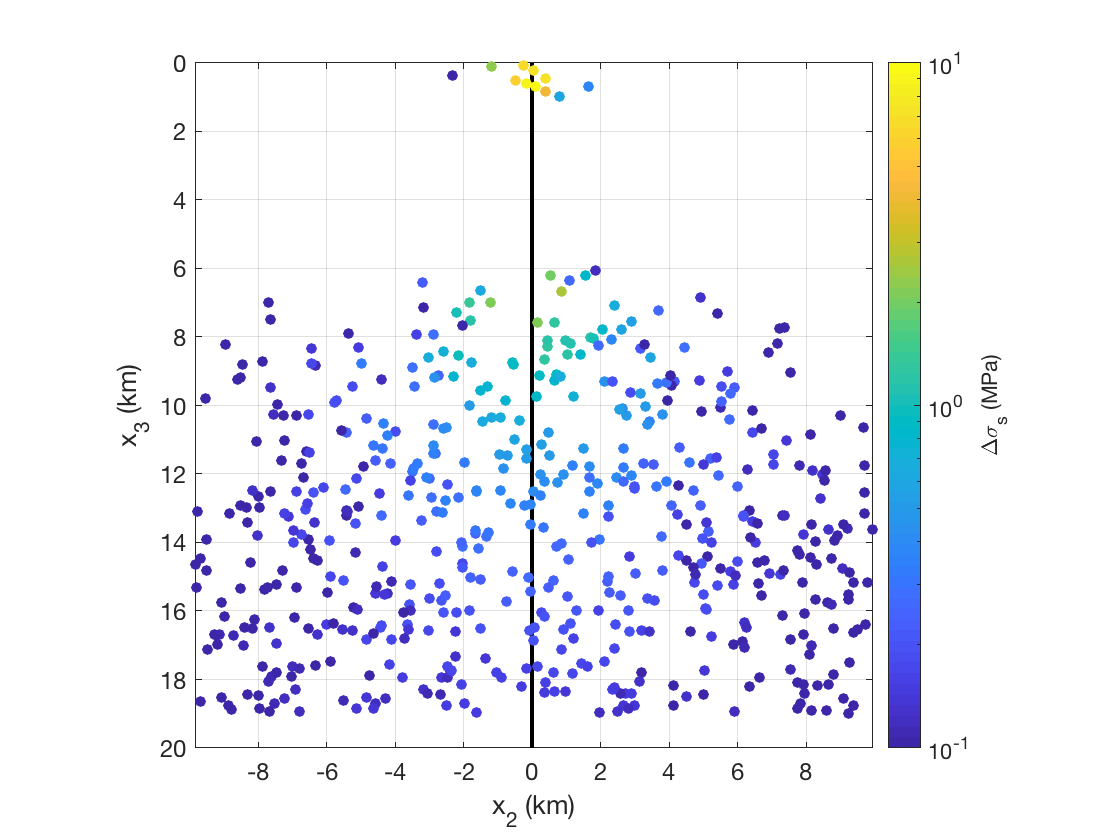

dat=readtable('aftershock_catalogue.dat');
x2ev = dat{:,1};
x3ev = dat{:,2};
dip = dat{:,3};
tvecev = dat{:,4};

% plot aftershock locations and stress drops
figure(1),clf
plot(zeros(100,1),linspace(0,20,100)','k-','LineWidth',2), hold on
scatter(x2ev./1e3,x3ev./1e3,30,tvecev,'filled','MarkerEdgeColor','none','LineWidth',.1)
axis tight equal, box on, grid on
xlabel('x_2 (km)'), ylabel('x_3 (km)')
cb=colorbar;
caxis(10.^[-1 1])
xlim([min(x2ev) max(x2ev)]./1e3)
cb.Label.String = '\Delta\sigma_{s} (MPa)';
set(gca,'YDir','reverse','FontSize',12,'ColorScale','log')
colormap parula

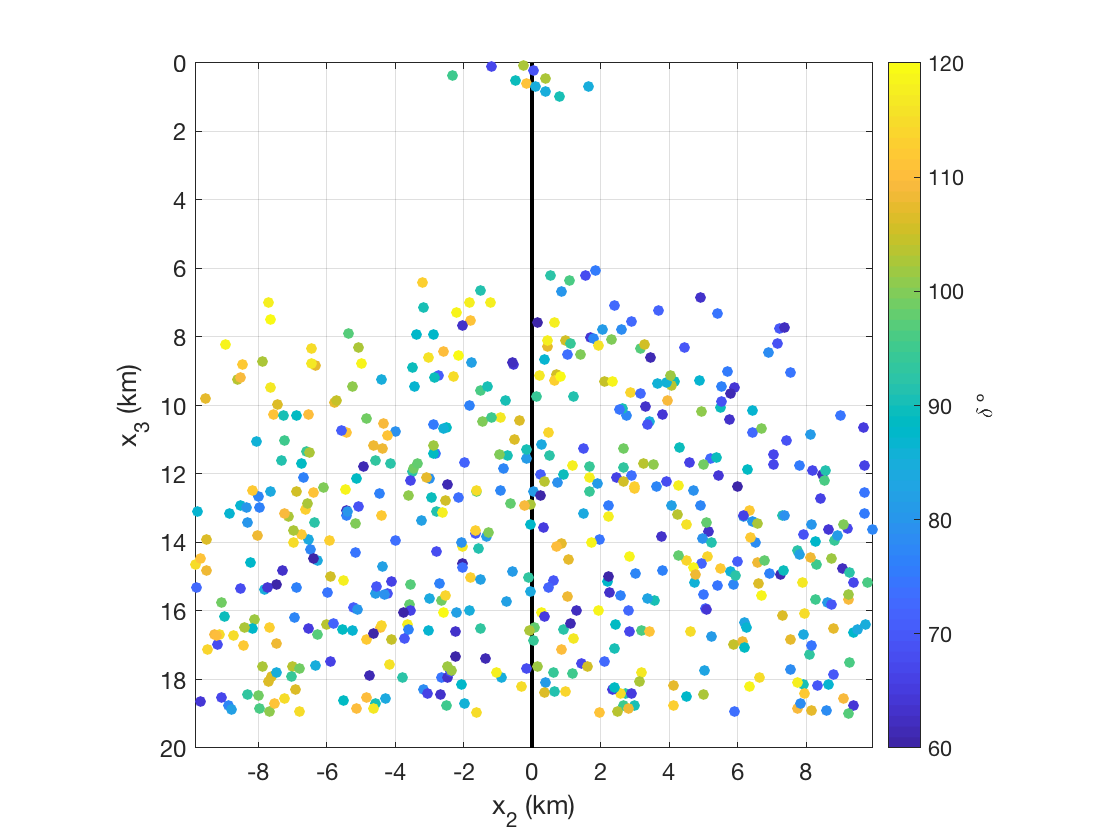

% plot aftershock dips
figure(2),clf
plot(zeros(100,1),linspace(0,20,100)','k-','LineWidth',2), hold on
scatter(x2ev./1e3,x3ev./1e3,30,dip,'filled','MarkerEdgeColor','none','LineWidth',.1)
axis tight equal, box on, grid on
xlabel('x_2 (km)'), ylabel('x_3 (km)')
cb=colorbar;
caxis([60 120])
xlim([min(x2ev) max(x2ev)]./1e3)
cb.Label.String = '\delta º';
set(gca,'YDir','reverse','FontSize',12)

- Using your best-fitting solution for fault slip, and information about aftershocks, compute the stress change on all fault patches and plot this.

- If the fault was being loaded by deep slip on a semi-infinite dislocation whose top edge is at 20 km, and we assume this earthquake dropped all the stress built up on this fault over the past 50 years in one-go, what is the slip rate of this fault?

Moving a bit further along-strike of this fault, some puzzling observations are made. The displacement field does not appear to be symmetric anymore, as shown below. The data is provided to you in the file '*eq2_obs.dat*'.

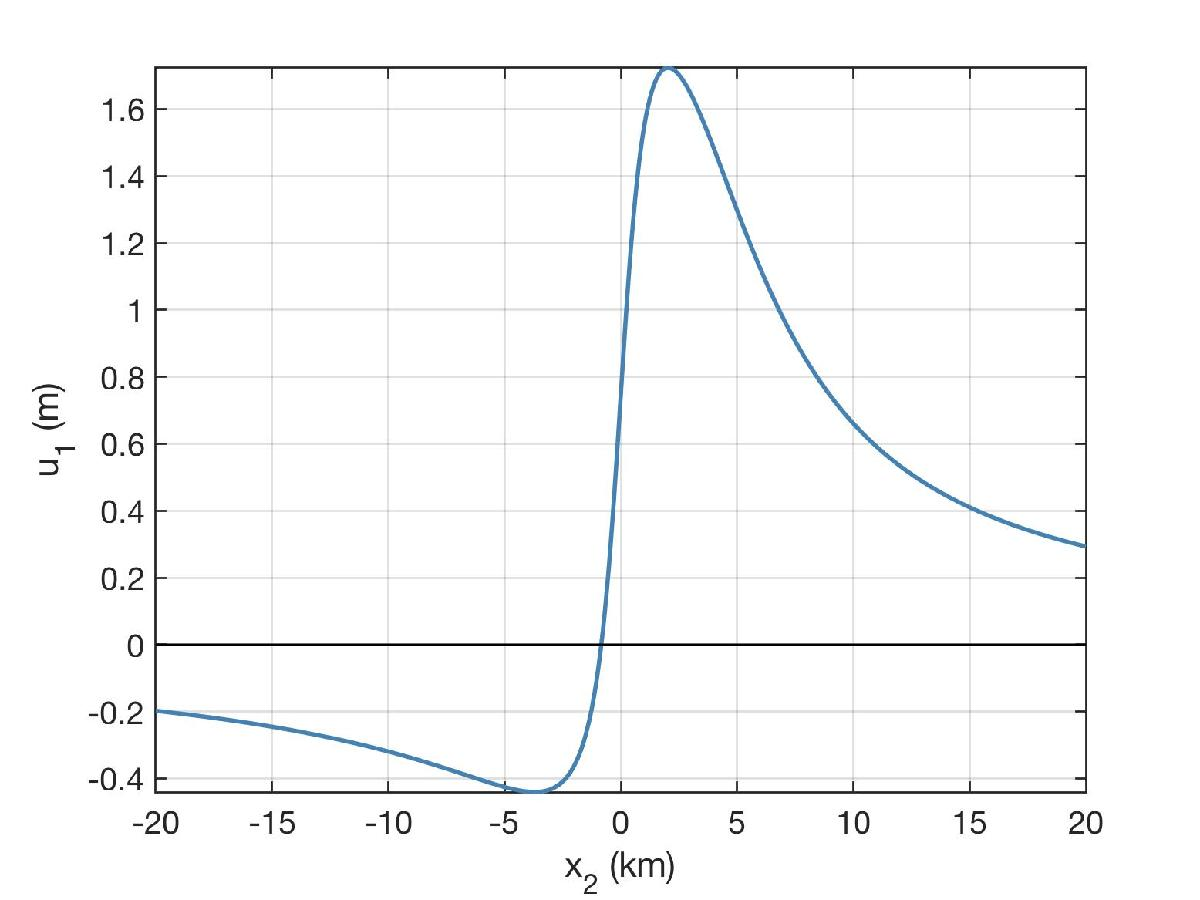

Provide an explanation for this unexpected behaviour, and calculate the slip on the fault at this location.

## Plane strain problems

Moving to subduction zones, the geometry is completely different from the anti-plane case, but the basic principles of slip, stress and displacements are identical. 

In this case you are provided with the surface displacements $\left(u_e,u_z\right)$ following a megathrust earthquake. From background seismicity and other seismological investigations, you are informed that the megathrust dips at 20º and the seismogenic width is at least 100 km long. The surface displacement observations are plotted below and provided in the file '*eq_planestrain.dat*'.

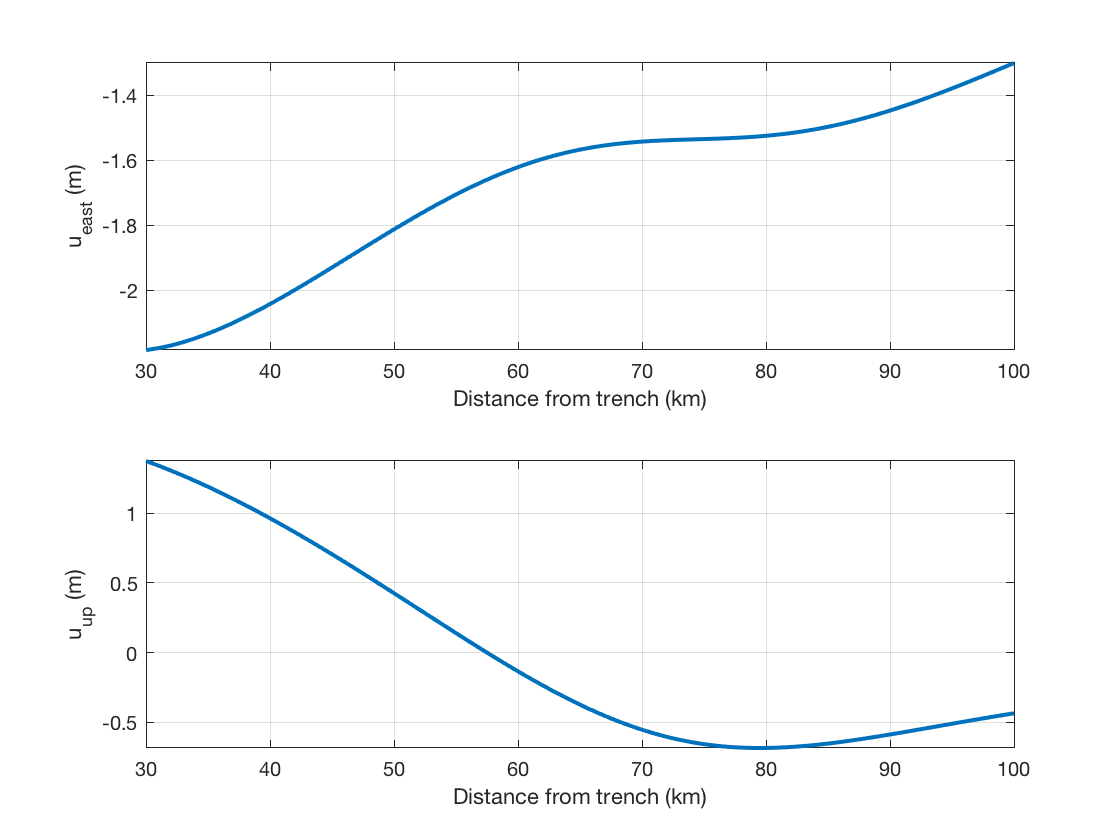

dat=readtable('eq_planestrain.dat');
x2 = dat{:,1};
ue = dat{:,2};
uz = dat{:,3};

figure(1),clf
subplot(211)
plot(x2./1e3,ue,'-','LineWidth',2)
axis tight, grid on, box on
xlabel('Distance from trench (km)')
ylabel('u_{east} (m)')
subplot(212)
plot(x2./1e3,uz,'-','LineWidth',2)
axis tight, grid on, box on
xlabel('Distance from trench (km)')
ylabel('u_{up} (m)')

Notice in these plots, the displacements are not available near the trench. This is a typical issue in subduction zone environments, since seafloor geodesy is not yet commonplace.

- Construct a model of slip on the megathrust that can explain the observed displacements. Discuss what can be resolved and what is not possible to resolve with the current distribution of stations.

- From the computed slip distribution, compute the stress change on the fault (shear traction). Predict the shear traction (computed in the megathrust slip direction) change in a 2-d region centered on the fault and extended 200 km in $x_2$ and 50 km in $x_3$.

- Use the work-based averaging method we have previously discussed in class to compute the average stress drop in this event. Recall that $W = \int (t.s) \,dA$, and the average stress drop $\Delta \tau_{\mathrm{av}} =\frac{\int \left(t\ldotp s\right)\;\mathrm{dA}\;\;}{\int s\;\mathrm{dA}\;}\;$

- If the entire coseismic region of the fault was locked interseismically, predict the 2-component interseismic surface velocity field. Use the concepts presented in Kanda and Simons, 2010 for this problem.

- Why does the back-slip model fail in the vertical dimension for plane-strain geometry? What other configurations can cause the back-slip assumption to breakdown?